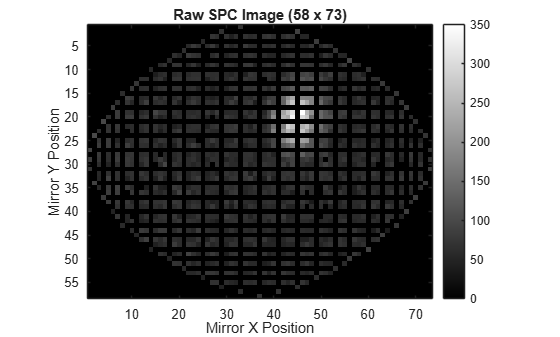

%% ============================================================
% SINGLE PHOTON CAMERA REAL DATA RECONSTRUCTION
%
% CSV
%  |
%  +--> Automatic Grid Detection
%  |
%  +--> SPC Frame
%  |
%  +--> Measured Scan Perimeter
%  |
%  +--> 2D Surrounding-Point Interpolation
%  |
%  +--> Background Correction
%  |
%  +--> Single-Point Star Detection
%
% The star is represented by ONE point at the maximum
% background-corrected photon count.
%
% OUTPUTS:
%
% 1. Raw SPC Image
% 2. Interpolated SPC Image
% 3. Interpolated + Background Corrected Image
% 4. Detected Star Position
% 5. Single-Point Star Map
%
% ============================================================

clear; clc; close all


%% ============================================================
% READ PHOTON COUNT CSV
% ============================================================

folder = '\\userfs\bh1308\w2k\Desktop\Single Photon Camera\CSV';

filename = uigetfile( ...
    fullfile(folder,'*.csv'), ...
    'Select Photon Scan File');

if isequal(filename,0)
    error('No file selected.');
end

data = readtable( ...
    fullfile(folder,filename));


%% ============================================================
% EXTRACT DATA
% ============================================================

mirrorX = data.X;
mirrorY = data.Y;
Counts  = data.Count;


%% ============================================================
% REMOVE INVALID DATA
% ============================================================

validData = isfinite(mirrorX) & ...
            isfinite(mirrorY) & ...
            isfinite(Counts);

mirrorX = mirrorX(validData);
mirrorY = mirrorY(validData);
Counts  = Counts(validData);


%% ============================================================
% AUTOMATIC GRID DETECTION
% ============================================================

x_sorted = sort(mirrorX);
y_sorted = sort(mirrorY);

dx = diff(x_sorted);
dy = diff(y_sorted);

% Remove extremely small differences
dx_nonzero = dx(abs(dx) > 1e-10);
dy_nonzero = dy(abs(dy) > 1e-10);

if isempty(dx_nonzero)
    error('Unable to determine X scan positions.');
end

if isempty(dy_nonzero)
    error('Unable to determine Y scan positions.');
end


%% ============================================================
% ESTIMATE GRID SPACING
% ============================================================

dx_sorted = sort(dx_nonzero);
dy_sorted = sort(dy_nonzero);

numX = max(1,round(length(dx_sorted)*0.25));
numY = max(1,round(length(dy_sorted)*0.25));

estimatedXSpacing = ...
    median(dx_sorted(1:numX));

estimatedYSpacing = ...
    median(dy_sorted(1:numY));


%% ============================================================
% POSITION TOLERANCE
% ============================================================

x_tolerance = ...
    estimatedXSpacing * 0.25;

y_tolerance = ...
    estimatedYSpacing * 0.25;


%% ============================================================
% CLUSTER X POSITIONS
% ============================================================

x_grid = x_sorted(1);

for k = 2:length(x_sorted)

    if abs(x_sorted(k) - x_grid(end)) ...
            > x_tolerance

        x_grid(end+1) = x_sorted(k);

    end

end


%% ============================================================
% CLUSTER Y POSITIONS
% ============================================================

y_grid = y_sorted(1);

for k = 2:length(y_sorted)

    if abs(y_sorted(k) - y_grid(end)) ...
            > y_tolerance

        y_grid(end+1) = y_sorted(k);

    end

end


%% ============================================================
% SORT GRID
% ============================================================

x_grid = sort(x_grid);
y_grid = sort(y_grid);

Nx = length(x_grid);
Ny = length(y_grid);


%% ============================================================
% MAP MEASUREMENTS ONTO GRID
% ============================================================

SPC_counts = zeros(Ny,Nx);
SPC_visits = zeros(Ny,Nx);


for k = 1:length(Counts)

    [x_error,x_index] = ...
        min(abs(x_grid - mirrorX(k)));

    [y_error,y_index] = ...
        min(abs(y_grid - mirrorY(k)));


    if x_error <= x_tolerance && ...
       y_error <= y_tolerance

        % Accumulate photon counts
        SPC_counts(y_index,x_index) = ...
            SPC_counts(y_index,x_index) + Counts(k);

        % Count number of measurements
        SPC_visits(y_index,x_index) = ...
            SPC_visits(y_index,x_index) + 1;

    end

end


%% ============================================================
% CALCULATE AVERAGE WHERE MEASUREMENTS EXIST
% ============================================================

SPC_frame = zeros(Ny,Nx);

measuredMask = SPC_visits > 0;

SPC_frame(measuredMask) = ...
    SPC_counts(measuredMask) ./ ...
    SPC_visits(measuredMask);


%% ============================================================
% DISPLAY RAW IMAGE
% ============================================================

figure

imagesc(rot90(SPC_frame))

axis image
axis ij

colormap(gray)
colorbar

title(sprintf( ...
    'Raw SPC Image (%d x %d)',Nx,Ny))

xlabel('Mirror X Position')
ylabel('Mirror Y Position')

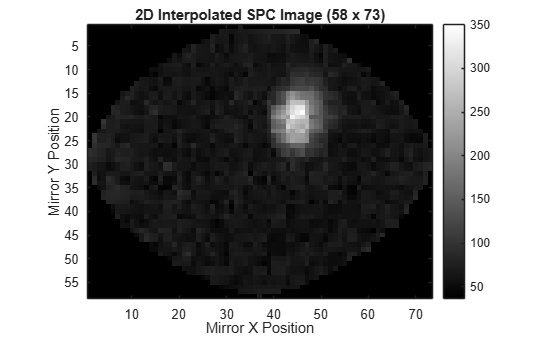



%% ============================================================
% FIND MEASURED SCAN PERIMETER
% ============================================================
%
% Interpolation is only allowed inside the area that was
% actually scanned.
%
% Nothing outside this perimeter will be generated.
%
% ============================================================

[row_measured,col_measured] = ...
    find(measuredMask);


if length(row_measured) >= 3

    % Create boundary around measured points
    shp = alphaShape( ...
        col_measured, ...
        row_measured, ...
        Inf);

    % Create grid coordinates
    [X_grid,Y_grid] = meshgrid( ...
        1:Nx, ...
        1:Ny);

    % Determine which grid locations are inside
    % the measured scan perimeter
    insidePerimeter = inShape( ...
        shp, ...
        X_grid, ...
        Y_grid);

else

    % If insufficient points exist, only measured
    % points are considered valid
    insidePerimeter = measuredMask;

end


% Everything outside the measured region
outsidePerimeter = ~insidePerimeter;


%% ============================================================
% 2D SURROUNDING-POINT INTERPOLATION
% ============================================================
%
% The interpolation uses surrounding measured points
% in BOTH X and Y.
%
% It does not simply interpolate horizontally and vertically.
%
% ============================================================

% Find measured grid locations
[row_measured,col_measured] = ...
    find(measuredMask);


% Convert grid indices into physical mirror coordinates
X_measured = ...
    x_grid(col_measured(:));

Y_measured = ...
    y_grid(row_measured(:));


% Extract measured photon counts
V_measured = ...
    SPC_frame(measuredMask);


% Force everything to column vectors
X_measured = X_measured(:);
Y_measured = Y_measured(:);
V_measured = V_measured(:);


%% ============================================================
% CREATE 2D INTERPOLANT
% ============================================================

F = scatteredInterpolant( ...
    X_measured, ...
    Y_measured, ...
    V_measured, ...
    'natural', ...
    'none');


%% ============================================================
% CREATE PHYSICAL GRID
% ============================================================

[X_physical,Y_physical] = ...
    meshgrid(x_grid,y_grid);


%% ============================================================
% INTERPOLATE USING SURROUNDING POINTS
% ============================================================

SPC_filled = F( ...
    X_physical, ...
    Y_physical);


%% ============================================================
% KEEP ORIGINAL MEASUREMENTS
% ============================================================
%
% Never overwrite an actual detector measurement
% with an interpolated value.
%
% ============================================================

SPC_filled(measuredMask) = ...
    SPC_frame(measuredMask);


%% ============================================================
% REMOVE ANYTHING OUTSIDE MEASURED PERIMETER
% ============================================================

SPC_filled(outsidePerimeter) = NaN;


%% ============================================================
% DISPLAY INTERPOLATED IMAGE
% ============================================================

figure

imagesc(rot90(SPC_filled))

axis image
axis ij

colormap(gray)
colorbar

title(sprintf( ...
    '2D Interpolated SPC Image (%d x %d)', ...
    Nx,Ny))

xlabel('Mirror X Position')
ylabel('Mirror Y Position')



%% ============================================================
% PREPARE FOR BACKGROUND CORRECTION
% ============================================================

Photon_input = SPC_filled;

% Outside the measured perimeter is not part of the image
Photon_input(isnan(Photon_input)) = 0;


%% ============================================================
% CALCULATE BACKGROUND
% ============================================================

backgroundCounts = Counts;

backgroundmedian = ...
    median(backgroundCounts);

sigma = ...
    std(backgroundCounts);


%% ============================================================
% BACKGROUND THRESHOLD
% ============================================================

k_threshold = -1;

threshold = ...
    backgroundmedian + ...
    k_threshold*sigma;


fprintf('\n')
fprintf('========================================\n')

fprintf('RECONSTRUCTION INFORMATION\n')

RECONSTRUCTION INFORMATION


fprintf('========================================\n')


fprintf('Grid size             = %d x %d\n', ...
    Nx,Ny);

Grid size             = 58 x 73



fprintf('Measured points       = %d\n', ...
    sum(measuredMask(:)));

Measured points       = 1328



fprintf('Expected grid points  = %d\n', ...
    Nx*Ny);

Expected grid points  = 4234



fprintf('Missing points        = %d\n', ...
    Nx*Ny-sum(measuredMask(:)));

Missing points        = 2906



fprintf('Background Median     = %.2f\n', ...
    backgroundmedian);

Background Median     = 65.00



fprintf('Background SD         = %.2f\n', ...
    sigma);

Background SD         = 32.69



fprintf('Threshold             = %.2f\n', ...
    threshold);

Threshold             = 32.31


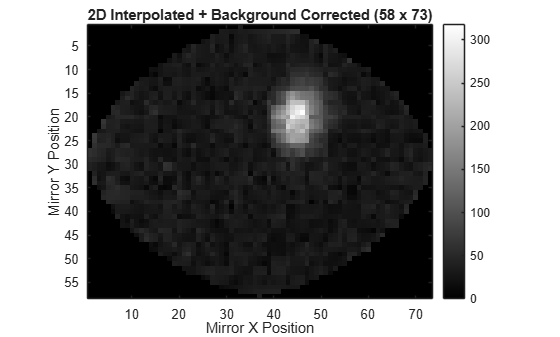



%% ============================================================
% BACKGROUND CORRECTION
% ============================================================

Photon_image = ...
    max(Photon_input - threshold,0);


% Keep outside perimeter empty
Photon_image(outsidePerimeter) = 0;


%% ============================================================
% DISPLAY BACKGROUND CORRECTED IMAGE
% ============================================================

figure

imagesc(rot90(Photon_image))

axis image
axis ij

colormap(gray)
colorbar

title(sprintf( ...
    '2D Interpolated + Background Corrected (%d x %d)', ...
    Nx,Ny))

xlabel('Mirror X Position')
ylabel('Mirror Y Position')



%% ============================================================
% FIND SINGLE STAR POINT
% ============================================================
%
% The star is represented by the position containing
% the maximum background-corrected photon count.
%
% ============================================================

[maxCount,linearIndex] = ...
    max(Photon_image(:));


%% ============================================================
% CONVERT LINEAR INDEX TO PIXEL POSITION
% ============================================================

[starY,starX] = ...
    ind2sub( ...
    size(Photon_image), ...
    linearIndex);


%% ============================================================
% CONVERT STAR PIXEL TO MIRROR POSITION
% ============================================================

starMirrorX = ...
    x_grid(starX);

starMirrorY = ...
    y_grid(starY);


%% ============================================================
% PRINT STAR POSITION
% ============================================================

fprintf('\n')
fprintf('========================================\n')

fprintf('SINGLE-POINT STAR DETECTION\n')

SINGLE-POINT STAR DETECTION


fprintf('========================================\n')


fprintf('Maximum corrected count = %.2f\n', ...
    maxCount);

Maximum corrected count = 317.69



fprintf('Pixel X                 = %d\n', ...
    starX);

Pixel X                 = 40



fprintf('Pixel Y                 = %d\n', ...
    starY);

Pixel Y                 = 46



fprintf('Mirror X                = %.6f\n', ...
    starMirrorX);

Mirror X                = 0.103001



fprintf('Mirror Y                = %.6f\n', ...
    starMirrorY);

Mirror Y                = 0.066365


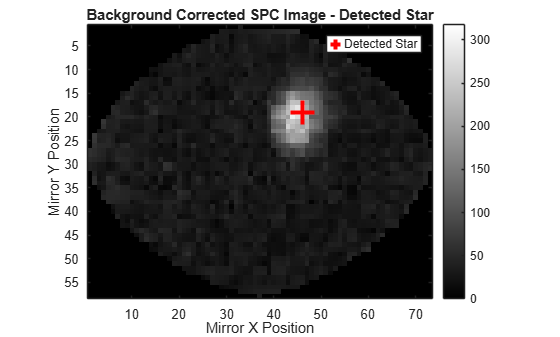



%% ============================================================
% DISPLAY DETECTED STAR
% ============================================================

figure

imagesc(rot90(Photon_image))

axis image
axis ij

colormap(gray)
colorbar

hold on


%% ============================================================
% CORRECT COORDINATES FOR rot90()
% ============================================================

displayX = starY;

displayY = ...
    Nx - starX + 1;


%% ============================================================
% PLOT SINGLE STAR POINT
% ============================================================

plot( ...
    displayX, ...
    displayY, ...
    'r+', ...
    'MarkerSize',18, ...
    'LineWidth',3);


title( ...
    'Background Corrected SPC Image - Detected Star')


xlabel('Mirror X Position')
ylabel('Mirror Y Position')

legend('Detected Star')

hold off

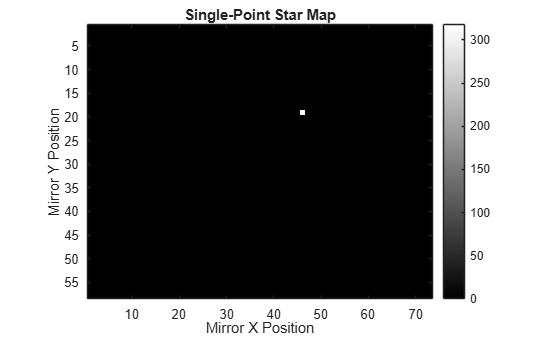



%% ============================================================
% CREATE SINGLE-POINT STAR IMAGE
% ============================================================

Star_point_image = ...
    zeros(Ny,Nx);

Star_point_image(starY,starX) = ...
    maxCount;


%% ============================================================
% DISPLAY SINGLE-POINT STAR MAP
% ============================================================

figure

imagesc(rot90(Star_point_image))

axis image
axis ij

colormap(gray)
colorbar

title('Single-Point Star Map')

xlabel('Mirror X Position')
ylabel('Mirror Y Position')

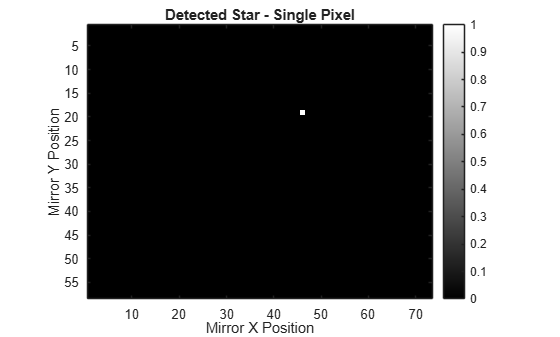



%% ============================================================
% CREATE BINARY STAR MAP
% ============================================================

Star_binary = ...
    zeros(Ny,Nx);

Star_binary(starY,starX) = 1;


%% ============================================================
% DISPLAY BINARY STAR MAP
% ============================================================

figure

imagesc(rot90(Star_binary))

axis image
axis ij

colormap(gray)
colorbar

title('Detected Star - Single Pixel')

xlabel('Mirror X Position')
ylabel('Mirror Y Position')



%% ============================================================
% FINAL INFORMATION
% ============================================================

fprintf('\n')
fprintf('========================================\n')

fprintf('RECONSTRUCTION COMPLETE\n')

RECONSTRUCTION COMPLETE


fprintf('========================================\n')


fprintf('Automatically detected grid = %d x %d\n', ...
    Nx,Ny);

Automatically detected grid = 58 x 73



fprintf('Interpolation method        = 2D Natural Neighbour\n');

Interpolation method        = 2D Natural Neighbour



fprintf('Interpolation restricted to = Measured perimeter\n');

Interpolation restricted to = Measured perimeter



fprintf('Detected star mirror X      = %.6f\n', ...
    starMirrorX);

Detected star mirror X      = 0.103001



fprintf('Detected star mirror Y      = %.6f\n', ...
    starMirrorY);

Detected star mirror Y      = 0.066365



fprintf('========================================\n')